# Airfoil: Eppler 197

clear; close all; clc;

## Flight Conditions Import

Re = 379824;
v = 24; %m/s
gamma = 1.4;
T = 286;
R = 286;

### Design Decisions

sweep_qc = 0; %quarter-chord sweep angle
sweep_max = 0;
d = 0.1; %fuselage diameter [m]
WL = 92.1058; %wing loading
Wg = 22.2297; %gross weight
AR = 4.5; %aspect ratio

## 2D Airfoil Data Import

Cl_alpha = 0.1182;
alpha0 = -2.669; %deg
Cl_min = -0.686;
Cl_max = 1.2295;
Cd_min = 0.0085;
TR = 0.1349;

## Wing Sizing

S = Wg/WL %reference wing area

S = 0.2413

b = sqrt(AR*S) %wing span

b = 1.0421

c = b/AR %chord length

c = 0.2316

## 3D Lift Analysis

####     Mach Number

a = sqrt(gamma*R*T); %local speed of sound
M = v/a

M = 0.0709

####     3D Lift Curve Parameters

CL_max = 0.9*Cl_max*cosd(sweep_qc)

CL_max = 1.1066

beta = sqrt(1 - M^2)

beta = 0.9975

eta = (Cl_alpha*180/pi) / (2*pi/beta)

eta = 1.0751

F = 1.07*(1+d/b)^2

F = 1.2852

Assuming that the reference area is equal to the exposed area, then the wetted area can be estimated. 

S_exp = S;
S_wet = S_exp*(1.977+0.52*TR)

S_wet = 0.4941

Calculating the 3D lift curve slope:

CL_alpha = ((2*pi*AR)/(2+sqrt(4+((AR^2*beta^2)/(eta^2))*(1+((tand(sweep_max)^2)/(beta^2))))))*(S_exp/S)*F;
CL_alpha = CL_alpha*pi/180

CL_alpha = 0.0957

####     Plotting 3D Lift Curve

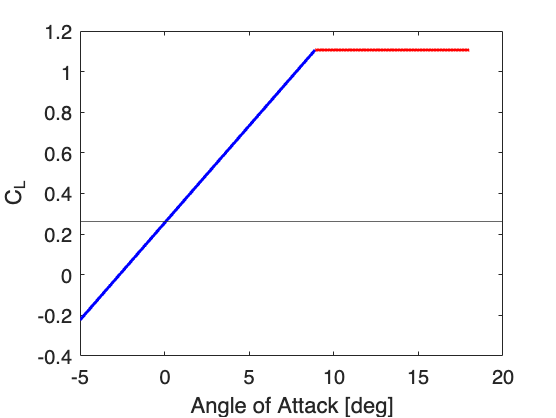

alpha_stall = (CL_max/CL_alpha) + alpha0;
alpha = linspace(-5,alpha_stall,100);
alpha_ps = linspace(alpha_stall,18,100);
CL_PS = CL_max*ones(1,length(alpha_ps));
CL = CL_alpha*(alpha - alpha0);

figure()
hold on
plot(alpha,CL,'-b','LineWidth',1.5)
plot(alpha_ps,CL_PS,'-r','LineWidth',1.5)
yline(0.26)
% grid on
xlabel('Angle of Attack [deg]')
ylabel('C_L')
box on
set(gca, 'LineWidth', 1)

## Drag Analysis

#### Open Airfoil Data from XFLR5

data = readtable('T1_Re0.380_M0.00_N9.0.txt', 'HeaderLines', 11);
    alpha_data = data.Var1;
    Cl_data = data.Var2;
    Cd_data = data.Var3;
    Cdp_data = data.Var4;
    Cm_data = data.Var5;
    TopXRT_data = data.Var6;
    BotXRT_data = data.Var7;
    Cpmin_data = data.Var8;
    Chinge_data = data.Var9;
    XCp_data = data.Var10;


#### 2D Drag Analysis

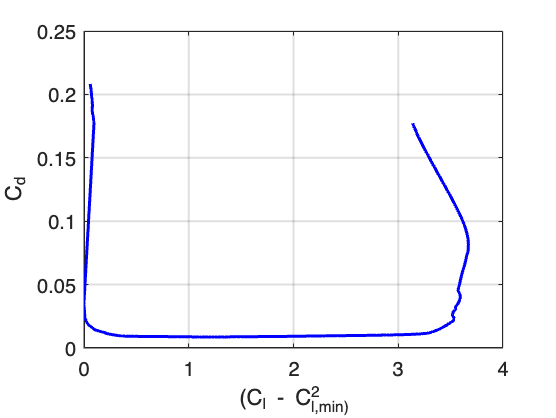

Cl_term = (Cl_data - Cl_min).^2;

figure()
plot(Cl_term,Cd_data,'-b','LineWidth',1.5)
xlabel('(C_l - C_l_,_m_i_n)^2')
ylabel('C_d')
box on
grid on
% xlim([1.5 3])
set(gca, 'LineWidth', 1)

## Drag Analysis (Part 5)

### Wing:

% Re = 379824;
x_c = 0.346;
t_c = 0.1349;
Q = 1.1;
S_wet_wing = 0.502191;
Cf = 0.455/((log10(Re))^2.58*(1+0.144*M^2)^0.65)

Cf = 0.0054

FFwing = (1 + 0.6/x_c * t_c + 100*(t_c)^4)*(1.34*M^0.18)

FFwing = 1.0545

Cd_min_wing = (Cf*FFwing*Q*S_wet_wing)/S

Cd_min_wing = 0.0130

### Fuselage:

S_wet_fuselage = 0.45984; % Haven't decided on sizing yet will update later
f_fuselage = 13.5;
FFfuselage = 1 + 60/(f_fuselage^3) + f_fuselage/400

FFfuselage = 1.0581

Cd_min_fuselage = (Cf*FFfuselage*Q*S_wet_fuselage)/S

Cd_min_fuselage = 0.0120

### Horizontal Stabilizers:

S_wet_Hstab = 0.144806; % Haven't chosen airfoil yet this is estimate
x_c_Hstab = 0.08;
t_c_Hstab = 0.346;
FFHstab = (1 + 0.6/x_c_Hstab * t_c_Hstab + 100*(t_c_Hstab)^4)*(1.34*M^0.18)

FFHstab = 4.1846

Cd_min_Hstab = (Cf*FFHstab*Q*S_wet_Hstab)/S

Cd_min_Hstab = 0.0149

### Vertical Stabilizer:

S_wet_Vstab = 0.5*S_wet_Hstab

S_wet_Vstab = 0.0724

% Assuming same airfoil as Horizontal Stabilizer, will change later
Cd_min_Vstab = (Cf*FFHstab*Q*S_wet_Vstab)/S

Cd_min_Vstab = 0.0074

### CD:

% Need to add Landing Gear and Motor. 
% Check slides for equations per unit frontal area
CD_min = Cd_min_wing + Cd_min_fuselage + Cd_min_Hstab + Cd_min_Vstab

CD_min = 0.0473

K = (0.01039-0.00898)/(2.98287-1.67107)

K = 0.0011

CL_min = min(CL);
e = 0.8;
CD = CD_min + K*(CL-CL_min).^2 + CL.^2/(pi*e*AR);

### Figures:

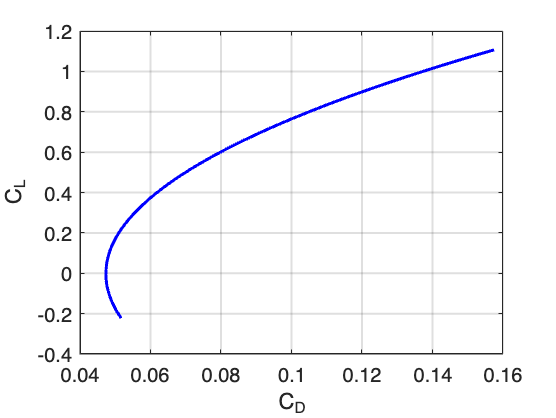

figure()
plot(CD,CL,'-b','LineWidth',1.5)
xlabel('C_D')
ylabel('C_L')
box on
grid on
set(gca, 'LineWidth', 1)

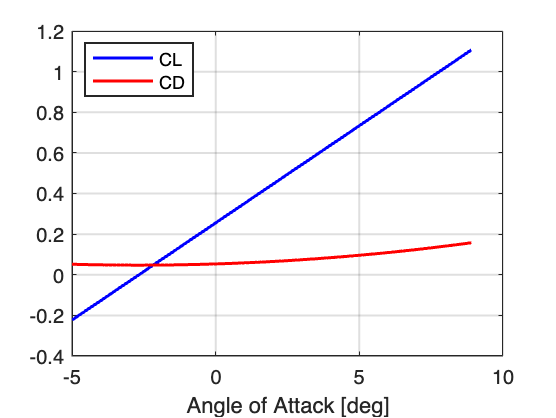


figure()
plot(alpha,CL,'-b','LineWidth',1.5)
hold on
plot(alpha,CD,'-r','LineWidth',1.5)
legend('CL','CD','Location','northwest')
xlabel('Angle of Attack [deg]')
box on
grid on
set(gca, 'LineWidth', 1)

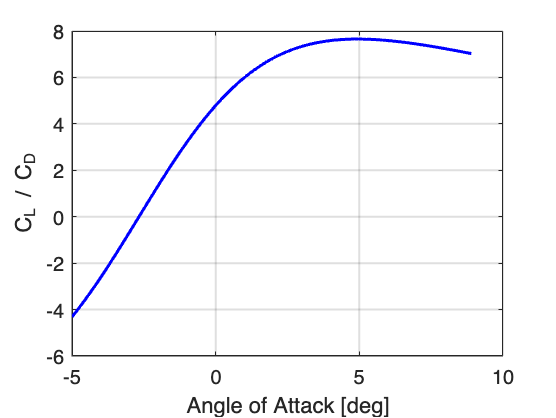


CLCD = CL./CD;
figure()
plot(alpha,CLCD,'-b','LineWidth',1.5)
xlabel('Angle of Attack [deg]')
ylabel('C_L / C_D')
box on
grid on
set(gca, 'LineWidth', 1)